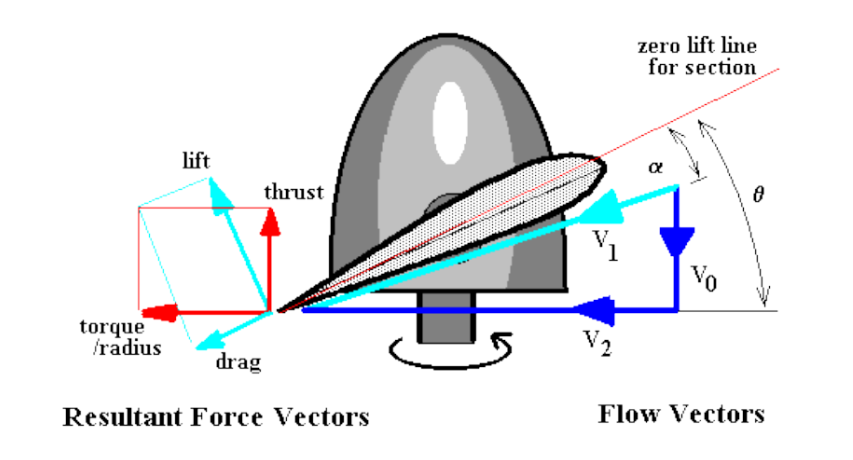

theta = 20;
alpha = 6;
rho = 1.225;

R = 0.60

R = 0.6000

V1 = 0;
V2 = 0;

B = 2;
trial_space = 10;
Trials = 5000;
start = 10

start = 10

Total_torque_Vs_Segments = zeros(1,Trials/trial_space);
Total_thrust_Vs_Segments = zeros(1,Trials/trial_space); 
Torque_Error = zeros(1,Trials/trial_space);
for h = start: trial_space: Trials

segments = h;
r_seg = 0:R/segments:R;
c=0.15;

torque_profile = zeros(1,length(r_seg));
thrust_profile = zeros(1,length(r_seg));
V0 = zeros(1,length(r_seg));
F= 9.8;
iterations =25;
torque_P = zeros (iterations,length(r_seg));
thrust_P = zeros (iterations,length(r_seg));
vortex_strength = zeros (iterations,length(r_seg));
vortex_tangentail_velcoity = zeros (1,length(r_seg));
total_torque =0;
Torque_thrust = F*R*2;
%omega=570
   
    omega =40.816 ;
    thrust_profile = zeros(1,length(r_seg));
    V02 = 0;
    for j = 1:iterations
    alpha = theta - atand(V02/(3./4.*R.*omega));

    for i = 1:length(r_seg)

        thrust_profile(i) = Thrust(Cl(alpha),rho,omega,r_seg(i),c,theta-alpha,Cd(alpha), B,V0(i),R/segments) * 0.98; % *0.98 to help account for Tip vortices
        torque_profile(i) = Torque(Cl(alpha),rho,omega,r_seg(i),c,theta-alpha,Cd(alpha), B,V0(i),R/segments);
        thrust_P(j,i)=thrust_profile(i);
        torque_P(j,i)=torque_profile(i);
    
    end

    total_thrust = sum(thrust_profile(4:end));
    total_torque = sum(torque_profile(4:end));
        CT = total_thrust ./ (pi.*R.^2.*rho.*(omega.*R).^2);
    tip_loss = 1 - sqrt(2.*CT)./2;
    V02 = sqrt(total_thrust.*tip_loss/(pi * R.^2 .* rho.*2));
    end
Total_torque_Vs_Segments(h/trial_space) = total_torque;
Total_thrust_Vs_Segments(h/trial_space) = total_thrust;
Torque_Error(h/trial_space) = (abs(total_thrust - 9.999814806846556))/9.999814806846556*100;

end
figure;
Total_torque_Vs_Segments

Total_torque_Vs_Segments =     4.9283    4.6441    4.5379    4.4837    4.4509    4.4290    4.4133    4.4016    4.3924    4.3851    4.3791    4.3741    4.3699    4.3663    4.3631    4.3604    4.3579    4.3558    4.3539    4.3521    4.3506    4.3491    4.3478    4.3466    4.3455    4.3445    4.3436    4.3427    4.3419    4.3411    4.3404    4.3398    4.3391    4.3386    4.3380    4.3375    4.3370    4.3365    4.3361    4.3357    4.3353    4.3349    4.3345    4.3342    4.3338    4.3335    4.3332    4.3329    4.3326    4.3324


Total_thrust_Vs_Segments

Total_thrust_Vs_Segments =    26.7158   25.5902   25.1648   24.9464   24.8141   24.7254   24.6619   24.6142   24.5770   24.5473   24.5229   24.5026   24.4855   24.4707   24.4580   24.4468   24.4369   24.4282   24.4203   24.4133   24.4069   24.4011   24.3958   24.3909   24.3864   24.3823   24.3785   24.3749   24.3716   24.3685   24.3656   24.3629   24.3604   24.3580   24.3558   24.3536   24.3516   24.3497   24.3479   24.3462   24.3445   24.3430   24.3415   24.3401   24.3387   24.3374   24.3362   24.3350   24.3338   24.3327


Torque_Error

Torque_Error =   167.1631  155.9072  151.6527  149.4687  148.1452  147.2585  146.6234  146.1463  145.7748  145.4774  145.2339  145.0309  144.8591  144.7118  144.5842  144.4724  144.3738  144.2861  144.2077  144.1371  144.0732  144.0151  143.9621  143.9135  143.8688  143.8275  143.7893  143.7538  143.7207  143.6899  143.6610  143.6339  143.6085  143.5846  143.5621  143.5408  143.5206  143.5015  143.4834  143.4662  143.4498  143.4342  143.4194  143.4052  143.3916  143.3787  143.3663  143.3544  143.3429  143.3320


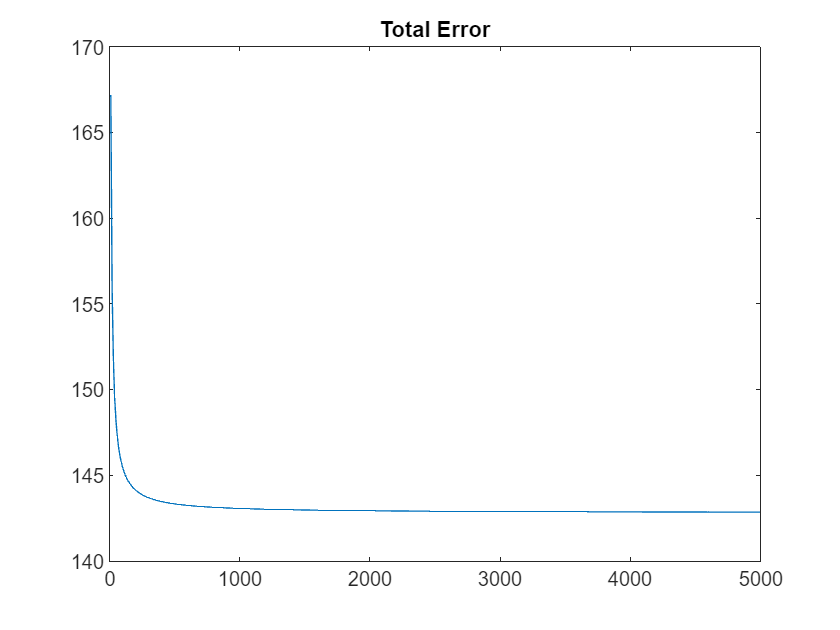

plot(start:trial_space:Trials,Torque_Error)
title(['Total Error']);

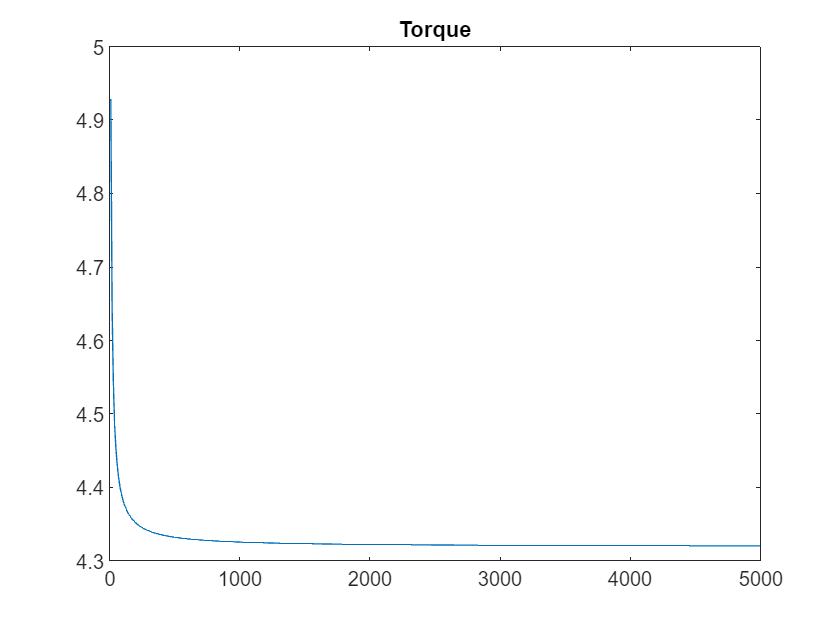

plot(start:trial_space:Trials,Total_torque_Vs_Segments)
title(['Torque']);

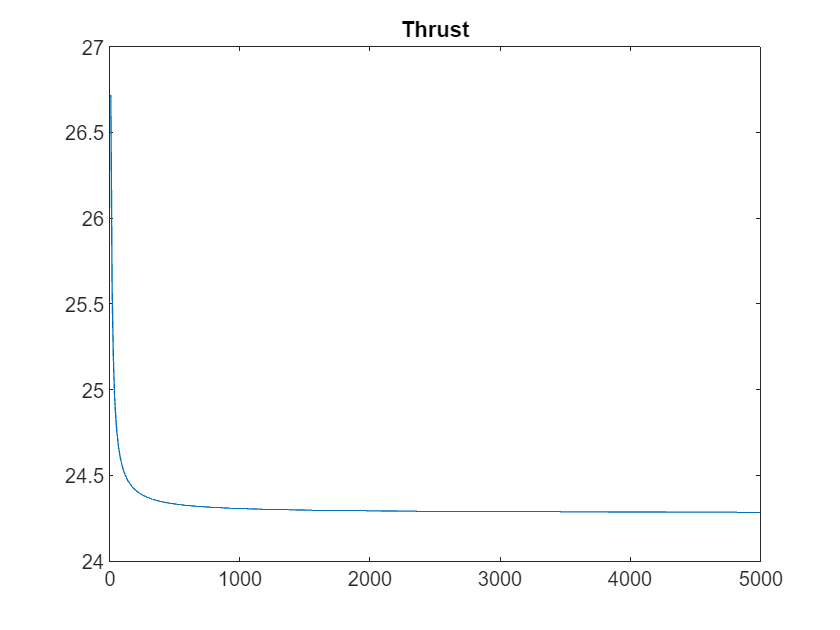

figure;
plot(start:trial_space:Trials,Total_thrust_Vs_Segments)
title('Thrust');

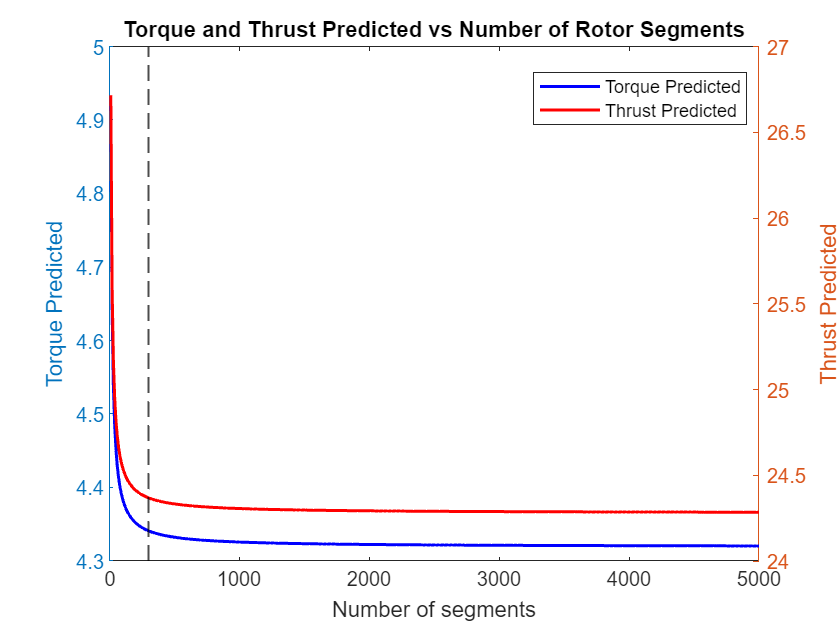

% V0
% plot(r_seg,torque_P)
% xlabel('Radius [m]');
% ylabel('Torque [Nm]');
% title(['Total Torque: ', num2str(total_torque)]);
% 
% plot(r_seg,thrust_P) 
% xlabel('Radius [m]');
% ylabel('Thrust [N]');
% title(['Total Thrust: ', num2str(total_thrust)]);
% alpha
figure;
yyaxis left
plot(start:trial_space:Trials, Total_torque_Vs_Segments, '-b', 'linewidth', 1.5);
ylabel('Torque Predicted');

yyaxis right
plot(start:trial_space:Trials, Total_thrust_Vs_Segments, '-r','linewidth', 1.5);
ylabel('Thrust Predicted');

xlabel('Number of segments');
xline(300,'--k','linewidth',1)
title('Torque and Thrust Predicted vs Number of Rotor Segments');
legend('Torque Predicted', 'Thrust Predicted');
legend("Position", [0.63586,0.80357,0.25357,0.082143])

(Total_torque_Vs_Segments(30)-Total_torque_Vs_Segments(end))/Total_torque_Vs_Segments(end)*100

ans = 0.4777

(Total_thrust_Vs_Segments(30)-Total_thrust_Vs_Segments(end))/Total_thrust_Vs_Segments(end)*100

ans = 0.3463


format long
Total_thrust_Vs_Segments(end)   

ans =   24.284432152237109


total_thrust(end)

ans =   24.284432152237109


format short

# Functions

function thrust = Thrust(Cl,rho,omega,r,c,phi,Cd,B,V0,L)
    V1 = sqrt((omega*r).^2 + (V0).^2);
    thrust = 1/2 * rho * V1^2 * (Cl * cosd(phi) - Cd * sind(phi)) * B * c * L;
end

function torque = Torque(Cl,rho,omega,r,c,phi,Cd,B,V0,L)
    V1 = sqrt((omega*r).^2 + (V0).^2);
    torque = 1/2 * rho * V1^2 * (Cd * cosd(phi) + Cl * sind(phi)) * B * c.*L;
end

function area_of_NACA = dr(c,t)
    NACA_f = @(x) 5.*t.*(0.2969.*sqrt(x) - 0.126.*x - 0.3156.*x.^2 + 0.2843.*x.^3 - 0.1015.*x.^4);
    area_of_NACA = 2*integral(NACA_f,0,c);
end

function lift_coefficent = Cl(alpha)
    lift_coefficent = 1./10 .* alpha + 0;
end

function drag_coeffcient = Cd(alpha)
    drag_coeffcient = 1.6e-4 .* alpha.^2 +0.005;
end

function omega = Omega_Estimate(Cl,rho,total_drag,c,phi,Cd,B,V0,L)
    V1_squared = 2.* total_drag / (rho * (Cd * cosd(phi) + Cl * sind(phi)) * B * c.*L);
    omega = sqrt((V1_squared) - (V0).^2)/(L);
end
